clc 
clear all

%static values
rho = 1.225; %SSL conditions
U_targ = 60; %m/s
U_max = 130; %m/s
deg_rad = pi/180;
max_tip_def = 1*deg_rad; %degrees
max_root_mom = 160; %N*m
alpha_bar_root = 4;

%aasks for dimensional values
s = 1.62

s = 1.6200

c1 = 0.158

c1 = 0.1580

c2 = 0.3101

c2 = 0.3101

c3 = 0.075

c3 = 0.0750

GJ1 = 1360

GJ1 = 1360

GJ2 = 750

GJ2 = 750

num_modes = 5

num_modes = 5


syms y
ada = y/s;
cord_eq = (c1+c2-((c2-c3)*ada));
cord_eq

$$cord\_eq = \frac{4681}{10000}-\frac{2351\,y}{16200}$$

a = 0;
b = s/2;
area = c1*s+c3*s+0.5*(c2-c3)*s;
MAC = (2/area)*int(cord_eq^2, a, b);
aileron = double(MAC*0.3);
aileron

aileron = 0.1444

y1 = (0.6*s)

y1 = 0.9720

y2 = (0.9*s)

y2 = 1.4580

AC = 0.75*cord_eq;
EA = c1;
EC = AC-c1;
Cla = 2*pi*sqrt(1-ada^2);
q = 0.5*rho*U_targ^2;
GJ = piecewise(ada < 0.6, GJ1, ada >= 0.6, GJ2);
alpha = deg_rad*(alpha_bar_root-3*ada);

%Cl = double(int(Cla*alpha,y, [0,s]))
%L = double(q*Cl*area*MAC)

for i = 1:1:num_modes
    f(i, 1) = y^i;
    f_prime(i, 1) = diff(f(i, 1));
end

%E = zeros(num_modes, num_modes);
%K = zeros(num_modes, num_modes);
%F = zeros(num_modes, 1);

for i= 1:1:num_modes
    for n = 1:1:num_modes
        E(n, i) = double(int((GJ)*f_prime(n).*f_prime(i), y, [0,s]));
        K(n, i) = -double(int((cord_eq)*EC*Cla*f(n)*f(i), y, [0,s]));
        F(n, 1) = q*double(int((cord_eq)*EC*Cla*alpha*f(n), y, [0,s]));
    end
end
E

E = 1.0e+05 *

    0.0181    0.0254    0.0375    0.0571    0.0890
    0.0254    0.0500    0.0857    0.1424    0.2345
    0.0375    0.0857    0.1602    0.2814    0.4813
    0.0571    0.1424    0.2814    0.5134    0.9016
    0.0890    0.2345    0.4813    0.9016    1.6141


K

K =    -0.1271   -0.1147   -0.1170   -0.1297   -0.1523
   -0.1147   -0.1170   -0.1297   -0.1523   -0.1870
   -0.1170   -0.1297   -0.1523   -0.1870   -0.2373
   -0.1297   -0.1523   -0.1870   -0.2373   -0.3094
   -0.1523   -0.1870   -0.2373   -0.3094   -0.4123


F

F =    17.6817
   11.3955
    9.3085
    8.7740
    9.1064


prelimval = -eig(E,K);
posval = prelimval(prelimval>0);
q_d = min(prelimval)

q_d = 1.0352e+04

U_d = sqrt(q_d*2/rho)

U_d = 130.0046

## part b


theta = double((inv(E + q*K))*F)

theta =     0.0392
   -0.0329
    0.0098
    0.0014
   -0.0010


for i=1:1:num_modes
    variationtheta(i) = theta(i)*f(i);
end
variationtheta = sum(variationtheta);
L = double(int(q*cord_eq*Cla*(variationtheta + alpha),y,[0,s]))

L = 400.7711

L_eqn = q*cord_eq*Cla*(variationtheta + alpha);
L_rigid_plot = q*cord_eq*Cla*(alpha);
M = double(int((q*cord_eq*Cla*(variationtheta+alpha)*y/2),y,[0,s]))

M = 111.4720

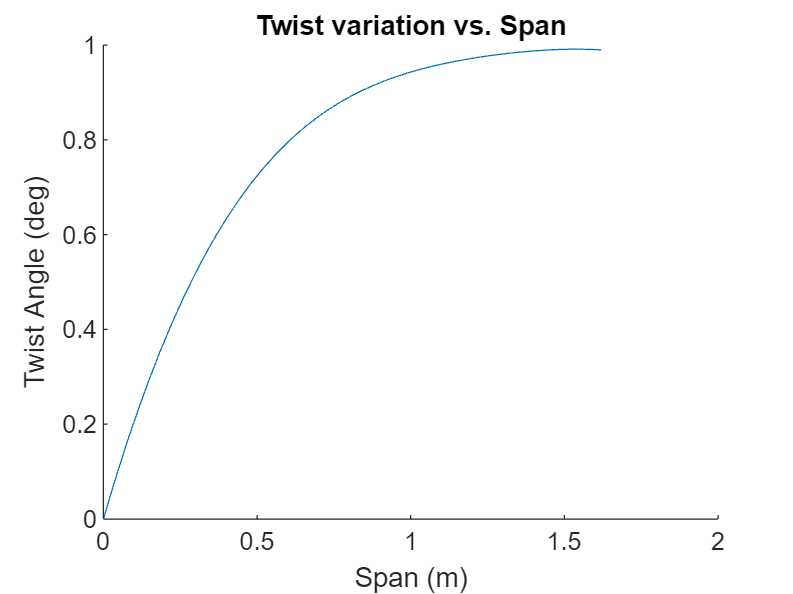


figure();
title ("Twist variation vs. Span")
hold on
fplot(variationtheta*(180/pi),[0,s,]);
xlabel("Span (m)")
ylabel("Twist Angle (deg)")
hold off


% find out if needed 5 percent increase on lift values and other
% parameters%

## part c


L_rig = q*cord_eq*Cla*alpha

$$L\_rig = \frac{\pi^{2}\,\left(\frac{50\,y}{27}-4\right)\,\left(\frac{115199\,y}{360}-\frac{2064321}{2000}\right)\,\sqrt{1-\frac{2500\,y^{2}}{6561}}}{90}$$

L_ela = q*cord_eq*Cla*(alpha+variationtheta)

$$L\_ela = -2\,\pi \,\left(\frac{115199\,y}{360}-\frac{2064321}{2000}\right)\,\sqrt{1-\frac{2500\,y^{2}}{6561}}\,\left(\frac{352953763374547\,y}{9007199254740992}-\frac{74165959899709\,y^{2}}{2251799813685248}+\frac{44177478610045\,y^{3}}{4503599627370496}+\frac{3128997373181\,y^{4}}{2251799813685248}-\frac{1114641469133\,y^{5}}{1125899906842624}-\frac{\pi \,\left(\frac{50\,y}{27}-4\right)}{180}\right)$$

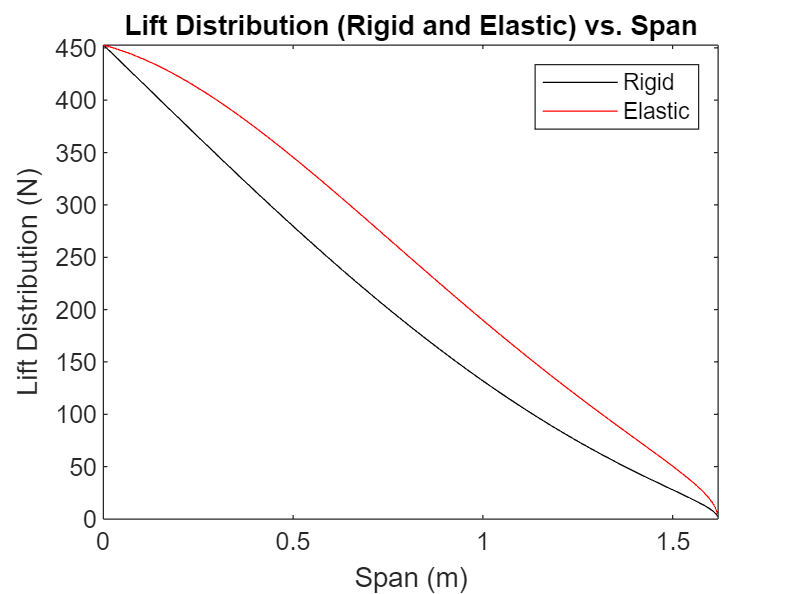

figure();
fplot(L_rig, [0,s,],'k-','LineWidth',0.5);
hold on
fplot(L_ela, [0, s], 'r-', 'LineWidth', 0.5);
title("Lift Distribution (Rigid and Elastic) vs. Span")
xlabel("Span (m)");
ylabel("Lift Distribution (N)");
legend('Rigid','Elastic');
hold off

## part d


L_rig_val = double(int(L_rig, y, [0,s]));
L_ela_val = double(int(L_ela, y, [0,s]));
perc_diff = ((L_ela_val-L_rig_val)/L_rig_val)*100

perc_diff = 23.6370

## part e

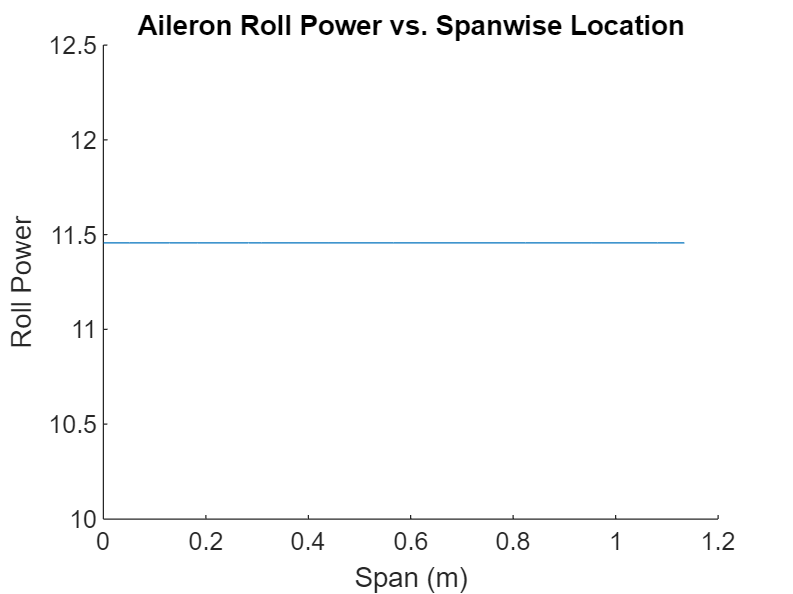



fa = y*(2*s-y);
%2d parameters 
phi = acos(2*aileron-1);
clb = 2*(pi-phi+sin(phi));
cmb = (-sin(phi)*(1-cos(phi)))/2;
%3d parameters
A = double(int(MAC*clb*y, y, [y1, y2]));
B = double(int(MAC^2*(EC*clb+cmb)*fa, y, [y1, y2]));   % CHECK EC VS C?????????????????
C = double(int(MAC*Cla*fa*y, y, [0,s]));
D = double(int((MAC^2)*EC*Cla*fa*fa, y, [0,s]));
Z = double(int(GJ*diff(fa)*diff(fa), y, [0,s]));
G = double(int(MAC^2*EC*Cla*fa*y, y, [0,s]));
N = double(int(MAC*Cla*y^2, y, [0,s]));
qr = ((A*Z)/(A*D-B*C));
qd = (Z/D);

proll_beta = double(U_targ*((A*(Z/q)-D)+(B*C))/((C*G)+N*(Z/q)-D));

% figure();
% title ("Aileron Roll Power vs. Spanwise Location")
% hold on
% fplot(proll_beta, [0, 0.7*s]); 
% ylabel ("Roll Power")
% xlabel("Span (m)")
% hold off 